# Entregable 2

## Esquema del robot

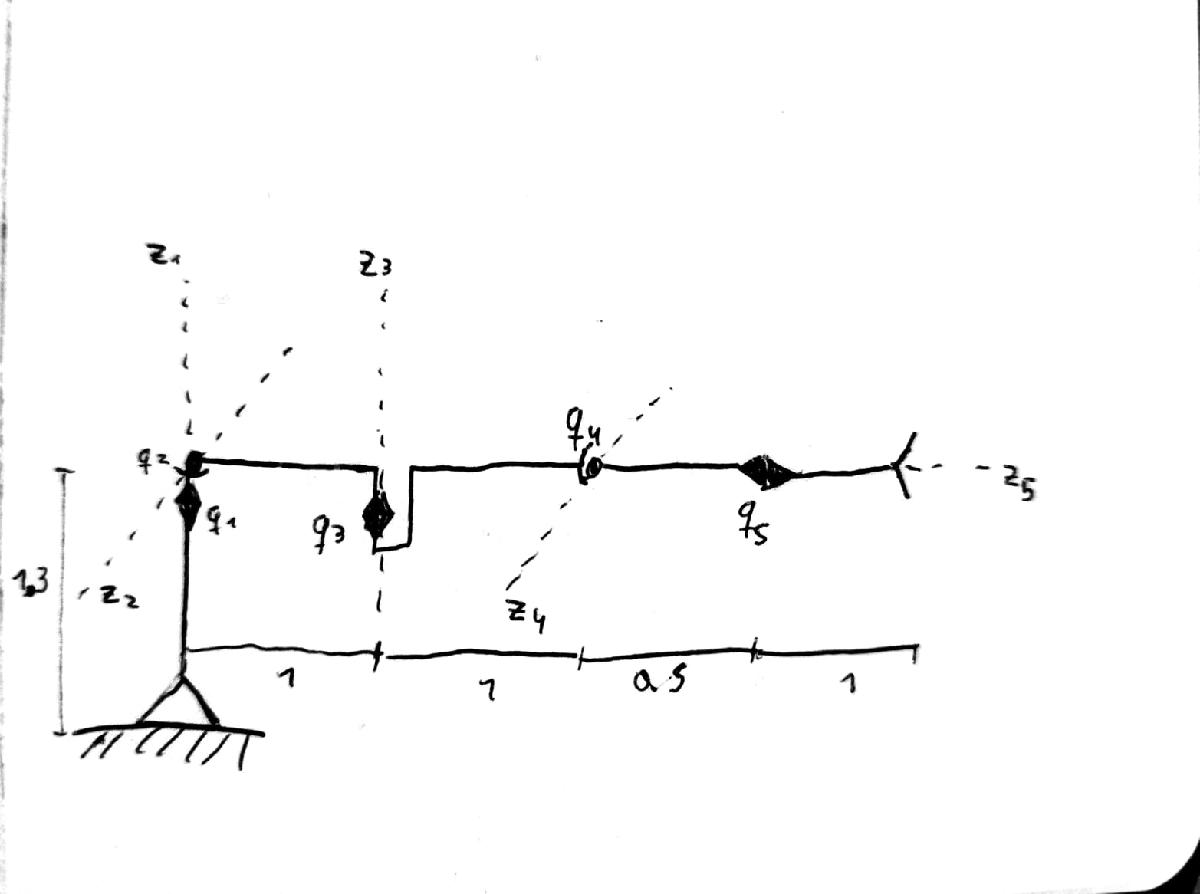

## Construir tabla de Denavit-Hatemberg

syms q1 q2 q3 q4 q5 l1 l2 l3 l4 l5

%La funcion DH la he creado obtener A a partir de cada entrada de la tabla
%de Denavit-Hatemberg
A0_1 = simplify(DH((q1*180/pi),   l1,0,     90))

$$A0\_1 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & 0\\ 0 & 1 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A1_2 = simplify(DH((q2*180/pi),   0, l2,   -90))

$$A1\_2 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & 0 & -\sin\left(q_{2}\right) & l_{2}\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & l_{2}\,\sin\left(q_{2}\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A2_3 = simplify(DH((q3*180/pi),   0, l3,   90 ))

$$A2\_3 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & 0 & \sin\left(q_{3}\right) & l_{3}\,\cos\left(q_{3}\right)\\ \sin\left(q_{3}\right) & 0 & -\cos\left(q_{3}\right) & l_{3}\,\sin\left(q_{3}\right)\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A3_4 = simplify(DH((q4*180/pi),   0, l4+l5,0  ))

$$A3\_4 = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & -\sin\left(q_{4}\right) & 0 & \cos\left(q_{4}\right)\,\left(l_{4}+l_{5}\right)\\ \sin\left(q_{4}\right) & \cos\left(q_{4}\right) & 0 & \sin\left(q_{4}\right)\,\left(l_{4}+l_{5}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A4_5 = simplify(DH(90+(q5*180/pi),0, 0,    90 ))

$$A4\_5 = \left(\begin{array}{cccc} -\sin\left(q_{5}\right) & 0 & \cos\left(q_{5}\right) & 0\\ \cos\left(q_{5}\right) & 0 & \sin\left(q_{5}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Cinemática directa

T = A0_1 * A1_2 * A2_3 * A3_4 * A4_5;
T = simplify(T)


Px = simplify(T(1,4))

$$Px = l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-l_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{4}\right)\,\left(l_{4}+l_{5}\right)\,\left(\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{4}\right)\,\left(l_{4}+l_{5}\right)+l_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)$$

Py = T(2,4)

$$Py = l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+l_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{4}\right)\,\left(l_{4}+l_{5}\right)\,\left(\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{4}\right)\,\left(l_{4}+l_{5}\right)+l_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)$$

Pz = T(3,4)

$$Pz = l_{1}+l_{2}\,\sin\left(q_{2}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{4}\right)\,\left(l_{4}+l_{5}\right)+l_{3}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)+\cos\left(q_{3}\right)\,\cos\left(q_{4}\right)\,\sin\left(q_{2}\right)\,\left(l_{4}+l_{5}\right)$$

## Cinemática Inversa

#### Suponiendo q2=0 y q5=0

Px = simplify(subs(Px, [q2,q5],[0,0]))

$$Px = l_{3}\,\cos\left(q_{1}+q_{3}\right)+l_{2}\,\cos\left(q_{1}\right)+\cos\left(q_{1}+q_{3}\right)\,\cos\left(q_{4}\right)\,\left(l_{4}+l_{5}\right)$$

Py = simplify(subs(Py, [q2,q5],[0,0]))

$$Py = l_{3}\,\sin\left(q_{1}+q_{3}\right)+l_{2}\,\sin\left(q_{1}\right)+\sin\left(q_{1}+q_{3}\right)\,\cos\left(q_{4}\right)\,\left(l_{4}+l_{5}\right)$$

Pz = simplify(subs(Pz, [q2,q5],[0,0]))

$$Pz = l_{1}+\sin\left(q_{4}\right)\,\left(l_{4}+l_{5}\right)$$


syms X Y Z

ik = solve([Px==X,Py==Y], [q1,q3],'Real', true);

solq1 = simplify(ik.q1,'Steps',30)

$$solq1 = \begin{array}{l} \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{\left(\sigma_{1}-\frac{8\,Y\,{l_{2}}^{2}\,\sigma_{4}}{\sigma_{3}\,\sigma_{2}}\right)\,\sigma_{2}}{4\,l_{2}\,\sigma_{4}}\right)\\ -2\,\mathrm{atan}\left(\frac{\left(\sigma_{1}+\frac{8\,Y\,{l_{2}}^{2}\,\sigma_{4}}{\sigma_{3}\,\sigma_{2}}\right)\,\sigma_{2}}{4\,l_{2}\,\sigma_{4}}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{4\,l_{2}\,\sigma_{4}\,\sqrt{-\frac{\sigma_{2}\,\left(-X^{2}-Y^{2}+{l_{2}}^{2}+2\,l_{2}\,l_{3}+2\,l_{2}\,l_{4}\,\cos\left(q_{4}\right)+2\,l_{2}\,l_{5}\,\cos\left(q_{4}\right)+{l_{3}}^{2}+2\,l_{3}\,l_{4}\,\cos\left(q_{4}\right)+2\,l_{3}\,l_{5}\,\cos\left(q_{4}\right)+\sigma_{7}+\sigma_{5}+\sigma_{6}\right)}{{\sigma_{3}}^{4}}}\,\sigma_{3}}{\sigma_{2}}\\ \sigma_{2}=-X^{2}-Y^{2}+{l_{2}}^{2}-2\,l_{2}\,l_{3}-2\,l_{2}\,l_{4}\,\cos\left(q_{4}\right)-2\,l_{2}\,l_{5}\,\cos\left(q_{4}\right)+{l_{3}}^{2}+2\,l_{3}\,l_{4}\,\cos\left(q_{4}\right)+2\,l_{3}\,l_{5}\,\cos\left(q_{4}\right)+\sigma_{7}+\sigma_{5}+\sigma_{6}\\ \sigma_{3}=-X^{2}-2\,X\,l_{2}-Y^{2}-{l_{2}}^{2}+{l_{3}}^{2}+2\,l_{3}\,l_{4}\,\cos\left(q_{4}\right)+2\,l_{3}\,l_{5}\,\cos\left(q_{4}\right)+\sigma_{7}+\sigma_{5}+\sigma_{6}\\ \sigma_{4}=l_{3}+l_{4}\,\cos\left(q_{4}\right)+l_{5}\,\cos\left(q_{4}\right)\\ \sigma_{5}=2\,l_{4}\,l_{5}\,{\cos\left(q_{4}\right)}^{2}\\ \sigma_{6}={l_{5}}^{2}\,{\cos\left(q_{4}\right)}^{2}\\ \sigma_{7}={l_{4}}^{2}\,{\cos\left(q_{4}\right)}^{2} \end{array}$$

solq3 = simplify(ik.q3,'Steps',30)

$$solq3 = \begin{array}{l} \left(\begin{array}{c} -\sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\mathrm{atan}\left(\frac{\sqrt{-\frac{\sigma_{2}\,\left(-X^{2}-Y^{2}+{l_{2}}^{2}+2\,l_{2}\,l_{3}+2\,l_{2}\,l_{4}\,\cos\left(q_{4}\right)+2\,l_{2}\,l_{5}\,\cos\left(q_{4}\right)+{l_{3}}^{2}+2\,l_{3}\,l_{4}\,\cos\left(q_{4}\right)+2\,l_{3}\,l_{5}\,\cos\left(q_{4}\right)+\sigma_{6}+\sigma_{4}+\sigma_{5}\right)}{{\sigma_{3}}^{4}}}\,{\sigma_{3}}^{2}}{\sigma_{2}}\right)\\ \sigma_{2}=-X^{2}-Y^{2}+{l_{2}}^{2}-2\,l_{2}\,l_{3}-2\,l_{2}\,l_{4}\,\cos\left(q_{4}\right)-2\,l_{2}\,l_{5}\,\cos\left(q_{4}\right)+{l_{3}}^{2}+2\,l_{3}\,l_{4}\,\cos\left(q_{4}\right)+2\,l_{3}\,l_{5}\,\cos\left(q_{4}\right)+\sigma_{6}+\sigma_{4}+\sigma_{5}\\ \sigma_{3}=-X^{2}-2\,X\,l_{2}-Y^{2}-{l_{2}}^{2}+{l_{3}}^{2}+2\,l_{3}\,l_{4}\,\cos\left(q_{4}\right)+2\,l_{3}\,l_{5}\,\cos\left(q_{4}\right)+\sigma_{6}+\sigma_{4}+\sigma_{5}\\ \sigma_{4}=2\,l_{4}\,l_{5}\,{\cos\left(q_{4}\right)}^{2}\\ \sigma_{5}={l_{5}}^{2}\,{\cos\left(q_{4}\right)}^{2}\\ \sigma_{6}={l_{4}}^{2}\,{\cos\left(q_{4}\right)}^{2} \end{array}$$

solq4 = simplify(solve([Pz==Z], [q4])) % Es lo mismo

$$solq4 = \left(\begin{array}{c} \mathrm{asin}\left(\frac{Z-l_{1}}{l_{4}+l_{5}}\right)\\ \pi -\mathrm{asin}\left(\frac{Z-l_{1}}{l_{4}+l_{5}}\right) \end{array}\right)$$

## Función para determinar la posicion

[q1,q2,q3,q4,q5] = Pos(-0.2,2.4,2.4) % Con los resultados del Aula Virtual

q1 =     0.6833    2.6246


q2 = 0

q3 =     1.3915   -1.3915


q4 = 0.8232

q5 = 0

[q1,q2,q3,q4,q5] = myPos(-0.2,2.4,2.4)  % Con mis resultados

q1 =     0.6833
    2.6246


q2 = 0

q3 =     1.3915
   -1.3915


q4 = 0.8232

q5 = 0

Aqui se puede ver que aunque den otra formula, en realidad son iguales.

% Mas ejemplos
% [q1,q2,q3,q4,q5] = Pos(2.8,-1,1.8)
% [q1,q2,q3,q4,q5] = Pos(1.4,-1.4,0)
% [q1,q2,q3,q4,q5] = Pos(3.25,0,1.3)
% [q1,q2,q3,q4,q5] = Pos(0.5,-2.25,0.1)